% a clear MATLAB workspace is a clear mental workspace
close all; clear

## create data for the plot

% data sizes
m = 30; % rows
n =  6; % columns

% generate data
data = bsxfun(@times,30*randn(m,n),linspace(-1,1,n).^2);
data = bsxfun(@plus,data,(1:n).^3);

## show it!

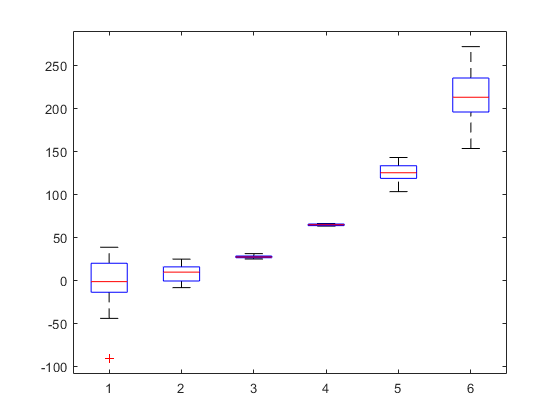

figure(1), clf

boxplot(data)

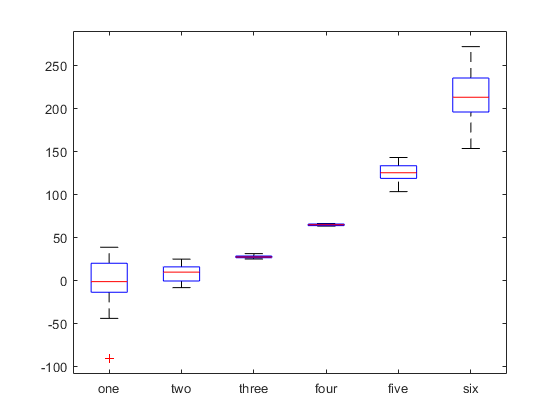


boxplot(data,{'one';'two';'three';'four';'five';'six'})

## alternative: data in a single column, grouped by a separate variable

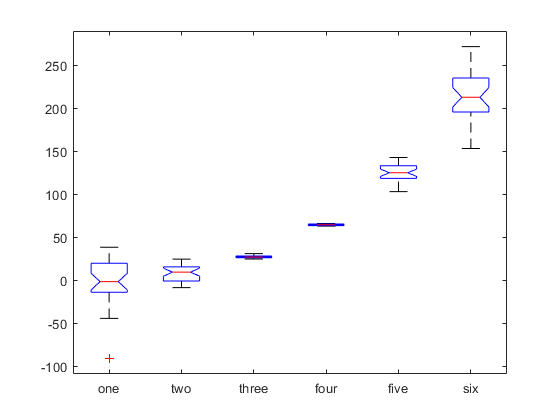

dataVect = data(:);
dataGrouping = ceil(linspace(eps,n,m*n));

figure(2), clf
boxplot(dataVect,dataGrouping,'notch','on','labels',{'one';'two';'three';'four';'five';'six'})


% for horizontal orientation
%boxplot(dataVect,dataGrouping,'notch','on','labels',{'one';'two';'three';'four';'five';'six'},'orientation','horizontal')

## Exercise.



N=23

N = 23

data1 = randn(N, 1);
data2 = rand(N, 1)

data2 =     0.6508
    0.7960
    0.2334
    0.6008
    0.1125
    0.5158
    0.8378
    0.9208
    0.4982
    0.2776


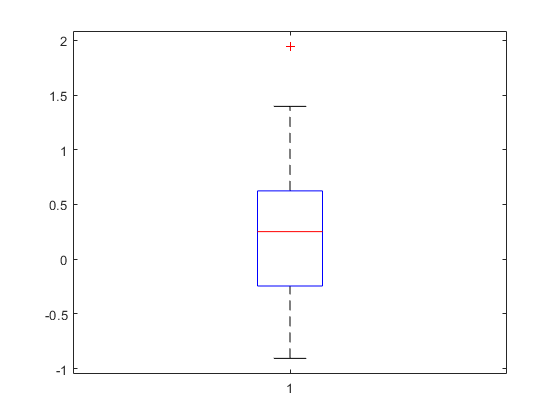




boxplot(data1)

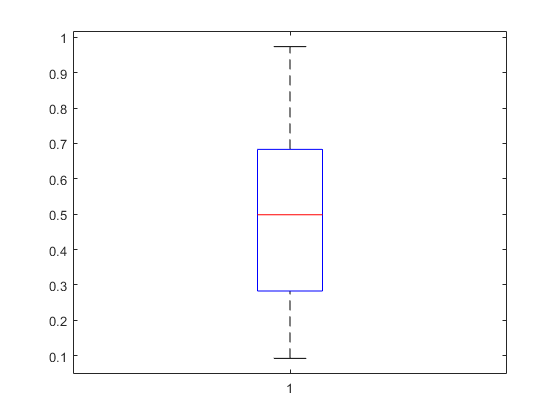

boxplot(data2)


merged = [data1, data2]

merged =     0.2519    0.6508
   -0.6104    0.7960
    0.7610    0.2334
    0.2544    0.6008
   -0.1528    0.1125
   -0.5574    0.5158
    0.6770    0.8378
    0.8493    0.9208
    0.4693    0.4982
   -0.2398    0.2776


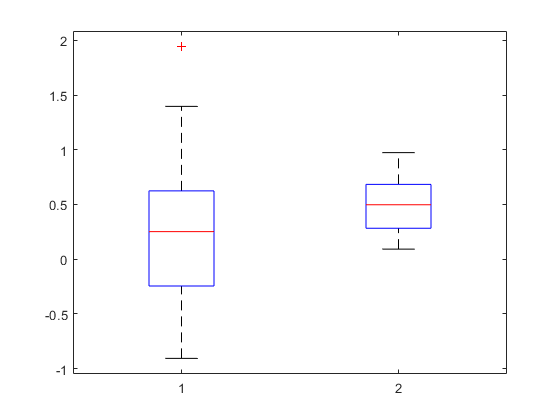


boxplot(merged)